# Scale Analysis to all Data

Now perform the same steps, using data from all years from 1980 - 2020. 

clear

## Create and update datastore

fileLoc = fullfile("StormData","StormEvents*.csv");
ds = datastore(fileLoc,"TextType","string"); 
ds.VariableNames = lower(ds.VariableNames); 
ds = updateDatastore(ds);
preview(ds)

ans = 8×14 table
     event_id       state      year       event_type         begin_timestamp        end_timestamp       damage_property    damage_crops    source    begin_lat    begin_lon    end_lat    end_lon    event_narrative
    __________    _________    ____    _________________    __________________    __________________    _______________    ____________    ______    _________    _________    _______    _______    _______________
    1.0046e+07    LOUISIANA    1980    Hail                 13-Apr-80 00:30:00   

## Create `tall` array

Create a `tall` array to work with data out of memory.

data = tall(ds);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


## Preprocess data

Perform the same preprocessing steps as before. 

data = data(data.source ~= "Unknown",:);
data = table2timetable(data);
data.storm_duration = data.end_timestamp - data.begin_timestamp;
[data,eventTypes,states] = PreprocessCategories(data);
data = PreprocessStrings(data);
data = rmmissing(data,"MinNumMissing",width(data));
% Remove data w/ missing sources
data = rmmissing(data,"DataVariables","source");

## Perform calculations

Do some analysis over the full data set such as summary stats of each event per year.

eventsOverTime = groupsummary(data,["year","weathercats"],"all","damage_total");

Explore the damage costs over time.

costOverTime = retime(data(:,["damage_property","damage_crops","damage_total"]),...
    "monthly","mean");

Get a random subset of the data (20%) to bring into memory. 

rng(1234) % set seed for reproducability
cv = cvpartition(data.weathercats,"HoldOut",0.8);
datasub = data(cv.training,:);

Remove the empty categories.

datasub.event_type = removecats(datasub.event_type);

## Gather results to memory

[datasub,eventTypes,states,eventsOverTime,costOverTime] = gather(...
    datasub,eventTypes,states,eventsOverTime,costOverTime);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 9: Completed in 18 sec
- Pass 2 of 9: Completed in 18 sec
- Pass 3 of 9: Completed in 18 sec
- Pass 4 of 9: Completed in 22 sec
- Pass 5 of 9: Completed in 23 sec
- Pass 6 of 9: Completed in 38 sec
- Pass 7 of 9: Completed in 45 sec
- Pass 8 of 9: Completed in 36 sec
- Pass 9 of 9: Completed in 11 sec
Evaluation completed in 4 min 2 sec


Visualize and explore the overall data.

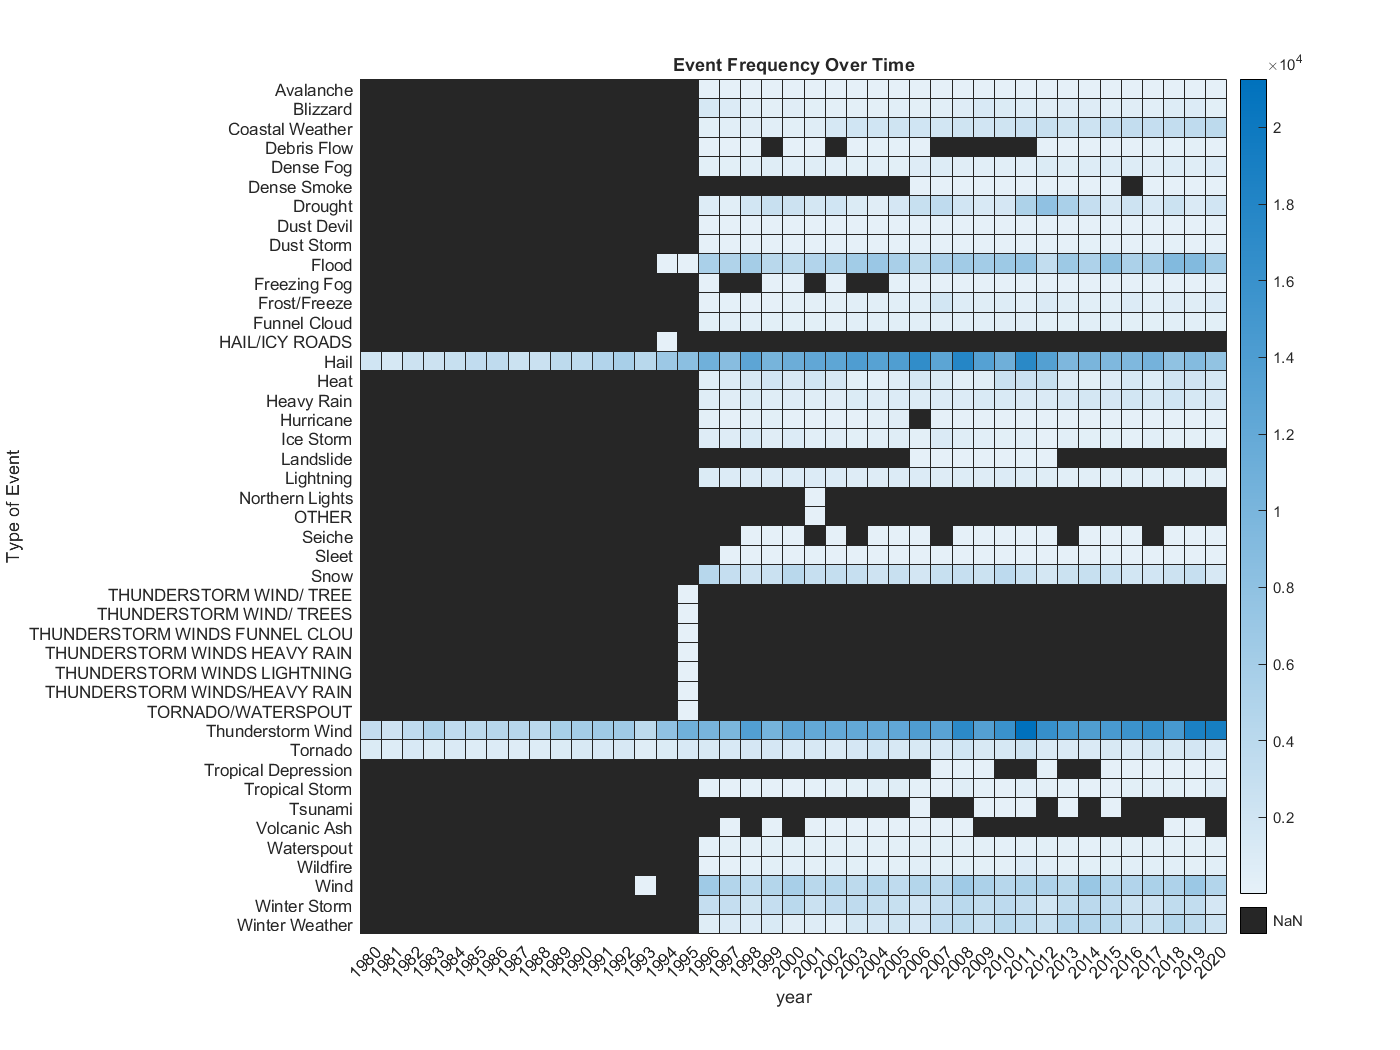

bigFigure;
heatmap(eventsOverTime,"year","weathercats","ColorVariable","GroupCount");
title("Event Frequency Over Time")
ylabel("Type of Event")

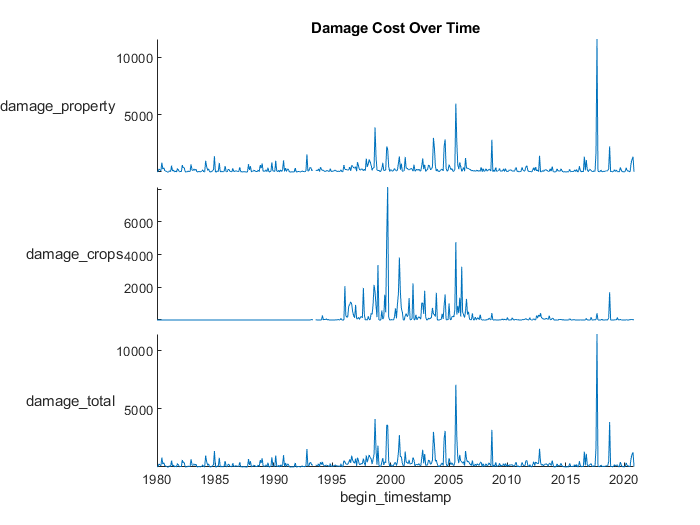

figure
stackedplot(costOverTime);
title("Damage Cost Over Time") 

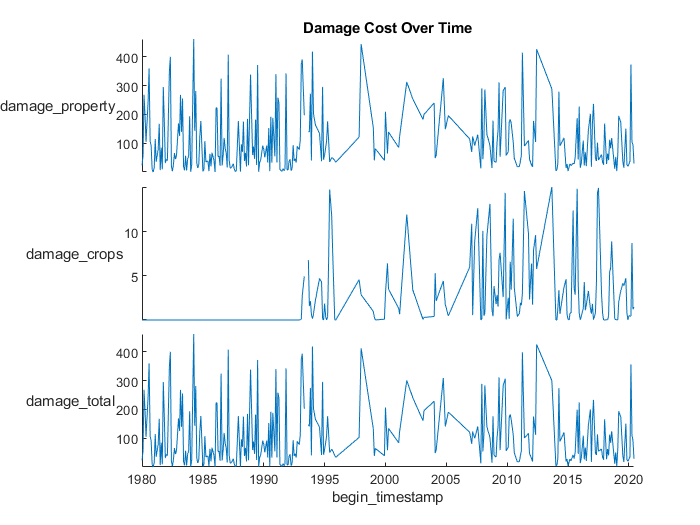

figure
stackedplot(rmoutliers(costOverTime));
title("Damage Cost Over Time") 

Update and save the preprocessed data.

datasub = removevars(datasub,["event_id","source","year"]);
datasub = rmmissing(datasub,"DataVariables","state");

Save a subset of the data as this is still large (over 1 million rows).

data = datasample(datasub,50000,'Replace',false);

% save preprocessedDataAll data states eventTypes eventsOverTime costOverTime

The next step is to build a model for predicting the damage cost.

edit PredictDamageCosts.mlx

**Helper functions**

function ds = updateDatastore(ds)
% Update data types
fmts = string(ds.SelectedFormats);
fmts([9,12:13]) = "%C";                       % Categorical
fmts([18,20]) = "%{dd-MMM-yy HH:mm:ss}D";     % Datetime
fmts(25:end) = "%q";                          % Text (string)
ds.SelectedFormats = fmts;
% Select data of interest by name
ds.VariableNames = replace(ds.VariableNames,"date_time","timestamp");
vars = ds.VariableNames;
% Filter the variables down to a subset of interest for this study
idx = ismember(vars,["year","state","source"]) | ...
    contains(vars,["lat","lon", ...
    "timestamp","damage","event"]);
ds.SelectedVariableNames = vars(idx);
end

*Copyright 2018 - 2021 The MathWorks, Inc.*